Rubén Vera Martínez, NIA: 241456

Sara Soriano Rossa, NIA: 240007

PROBLEM 1

a) Calculate the sample standard deviation $\hat{\sigma}$ for these weights and find the bias of $\hat{\sigma}$. 

b) Use bootstrapping to find the bootstrap standard error for $\hat{\sigma}$.

X = SM22Lab4WeightsRunners{:,:};
theta_hat = std(X);
n = length(X);
B = 1e4;
theta_rep= zeros(1, B);
rng(0);
for j=1:B
    rs_indx = ceil(n*rand(1,n));
    X_boot = X(rs_indx);
    theta_rep(j) = std(X_boot);
end
bias = mean(theta_rep) - theta_hat;
std_error = std(theta_rep);

c) Make a histogram of the bootstrap replications of $\hat{\sigma}$ from (b). Inspect the data to try assessing why do we obtain such a strange histogram.

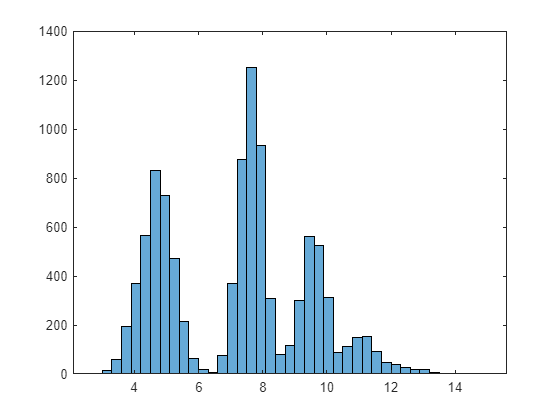

histogram(theta_rep);

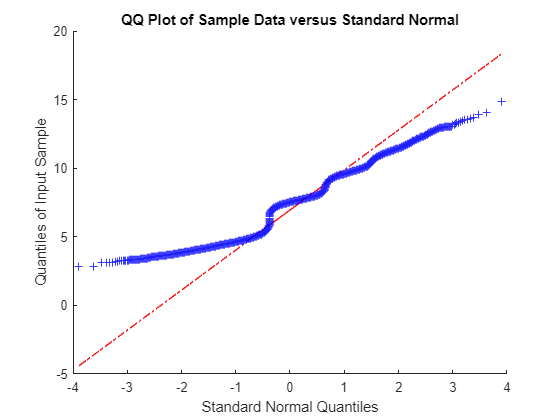

qqplot(theta_rep); % Refusem normalitat.

d) Suggest a way to improve the analysis so that you can compute a confidence interval using boot-strapping. Justify clearly why your proposal is adequate.

Al no ser los datos normales, usaremos el metodo percentile-based.

e) Implement the solution proposed in (d) and compute a confidence interval for $\hat{\sigma}$. Clearly indicate what method you choose to compute the interval.

Method chosen: Percentile-based method

alpha = 0.05;
theta_biasCorrected = 2*theta_hat-mean(theta_rep)

theta_biasCorrected = 8.1889

theta_rep_sort = sort(theta_rep);
conf_interval = [2*theta_biasCorrected - theta_rep_sort(round((B)*(1-alpha/2))), 2*theta_biasCorrected-theta_rep_sort(round((B)*(alpha/2)));]

conf_interval =     4.9703   12.5047


PROBLEM 3

a) Use bootstrapping to assess if the distribution of the sample skewness can be assumed normal. Clearly indicate your conclusion.

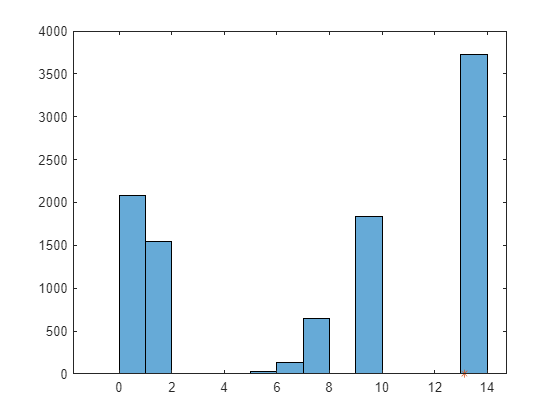

X = SM22Lab4HeightandWeight{:,:};
X(:,2) = X(:,2)/100;
n = size(X, 1);
B = 1e4;
BMI = zeros(n,1);
for i=1:n
    BMI(i) = X(i,1)/(X(i,2)^2);
end
theta_hat = skewness(BMI);
theta_rep = zeros(B, 1);
rng(0);
for j = 1:B
    rs_idx = ceil(n*rand(1,n));
    X_boot = BMI(rs_idx,:); 
    theta_rep(j) = skewness(X_boot); %Sample skewness of each columnn in X
end

histogram(theta_rep)
hold on
plot(theta_hat, 0, '*')
hold off

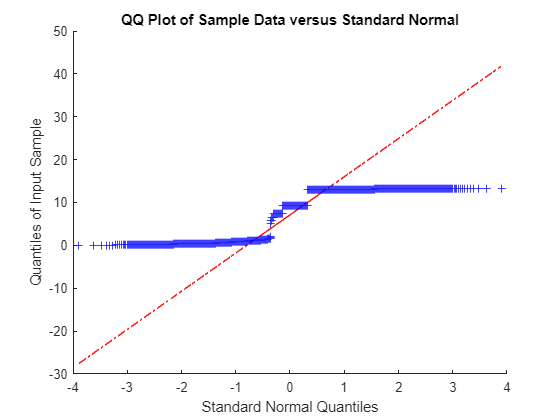

qqplot(theta_rep);

b) Based on the bootstrap from (a), estimate the standard error and the bias of your estimator. 

std_error = std(theta_rep)

std_error = 5.3116

bias = mean(theta_rep) - theta_hat

bias = -5.6169

c) Estimate a 95% confidence interval for the skewness using student’s t. Based on your analysis from (b), discuss whether this is likely to be accurate or not. 

alpha = 0.05;
theta_biasCorrected = 2*theta_hat-mean(theta_rep)

theta_biasCorrected = 18.7443

conf_interval = [theta_biasCorrected-tinv(alpha/2, n-1)*std_error theta_biasCorrected+tinv(alpha/2, n-1)*std_error]

conf_interval =    29.2261    8.2626


d) Compute a 95% confidence interval for the skewness using the percentiles of the bootstrap distribution. Clearly indicate your conclusion regarding the research question.

%percentile-based conf intervals
alpha = 0.05;
theta_rep_sort = sort(theta_rep);
conf_interval = [2*theta_biasCorrected - theta_rep_sort(round((B)*(1-alpha/2))), 2*theta_biasCorrected-theta_rep_sort(round((B)*(alpha/2)));]

conf_interval =    24.3317   37.1229
